clc
clear

**1.3.1**

1

syms t1
ans1=int(sin(5.*t1)^2,0,2*pi)

$$ans1 = \pi$$

2

syms t2
ans2=int(exp(t2),0,1)

$$ans2 = \mathrm{e}-1$$

**1.3.2**

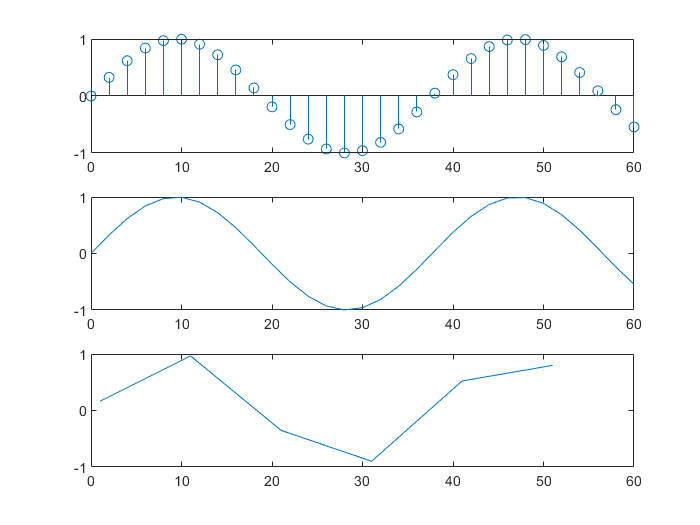

figure
n=0:2:60;
y=sin(n/6);
subplot(3,1,1)
stem(n,y);

n1=0:2:60;
z=sin(n1/6);
subplot(3,1,2)
plot(n1,z);

n2=1:10:60;
w=sin(n2/6);
subplot(3,1,3)
plot(n2,w);

**1.3.3**

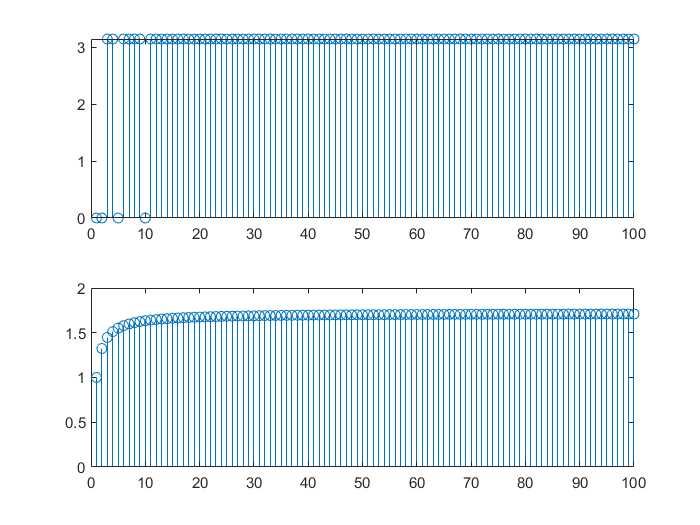

figure
subplot(2,1,1);
I=zeros(1,100);
N=1:1:100;
for i=1:1:100
    [I(i)]=Integ1(i);
end
stem(N,I);
subplot(2,1,2);
J=zeros(1,100);
for i=1:1:100
    [J(i)]=Integ2(i);
end
stem(N,J);

I5=I10=0，because when N is 5,10

n=(2*pi)/N;

t=0:n:2*pi-n;

area=sin((5.*t)).^2; the value of area keeps zero

**1.4**

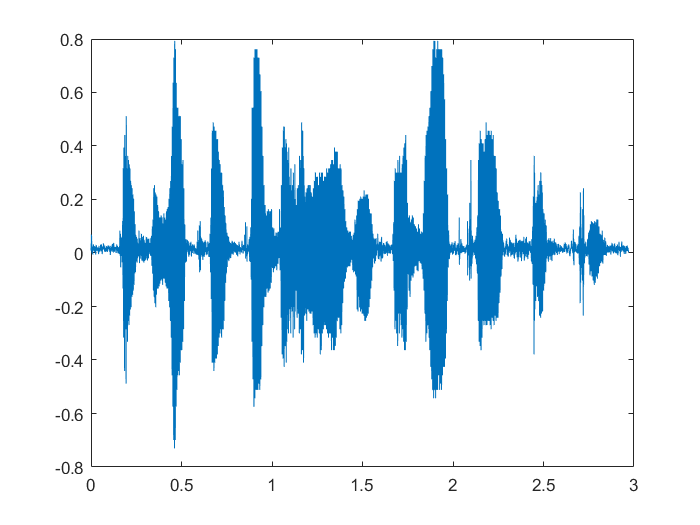

[y,Fs]=audioread("speech.au");%output y and fs sampling frequency
y=y(:,1);% extract the first column of the matrix y 
y=y';%transpose
N=length(y);t=(0:N-1)/Fs;%get the x axis
figure
plot(t,y);